# Calcium Imaging Analysis

By Brian Carson from the Cheer Lab, for extraction of neuron spikes and ensembles from calcium imaging videos. 

The first section takes in a video file and converts it into a 3D variable of resized frames. 

addpath('Ca Vids'); %optional - add folder to path
v=VideoReader('msCam1.avi');
vlen=round(v.Duration*v.FrameRate)-1; %doesn't always come out as a whole number and is therefor rounded down 1.
for i=1:vlen
    frame=readFrame(v);
    compressedframe=imresize(frame(:,:,1),[v.Height/2,v.Width/2]); %resized to save memory
    comp(:,:,i)=squeeze(compressedframe); %squeeze out singleton dimensions
end
 

## Data Exploration

The raw frames are median filtered then subtracted from the raw data. This leaves the most prominent sections of the video (ie. neurons) in the variable 'c'. 

cm=medfilt3(comp,[19, 19, 3]); % filter with size [x, y, z]
c=comp-1.05*cm; %subtract background

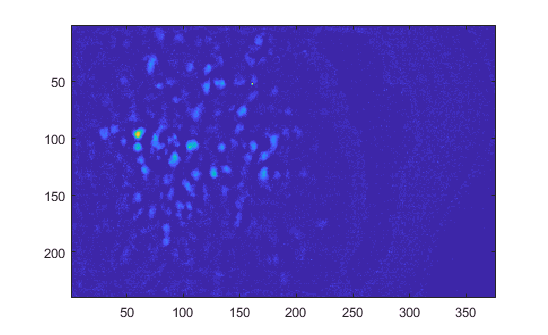

 
imagesc(max(c,[],3)-medfilt2(max(c,[],3),[15 15]))

Visualize various aspects of the video: mean raw frame, mean filtered frame, mean background subtracted frame, and detected structure.

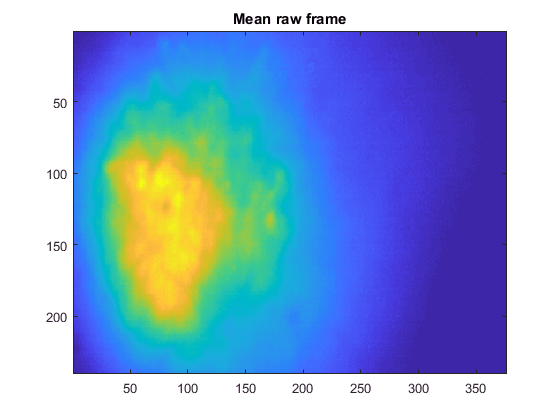

imagesc(squeeze(mean(comp,3)))
title('Mean raw frame')

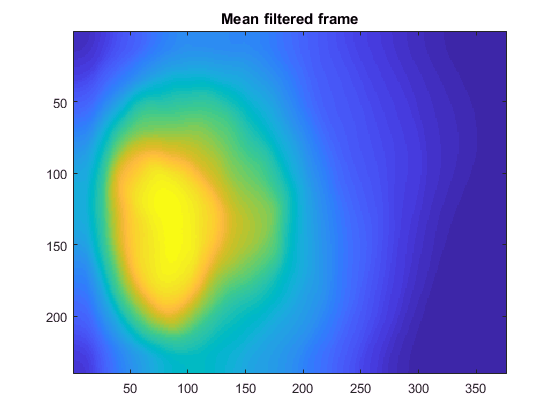

imagesc(squeeze(mean(cm,3)))
title('Mean filtered frame')

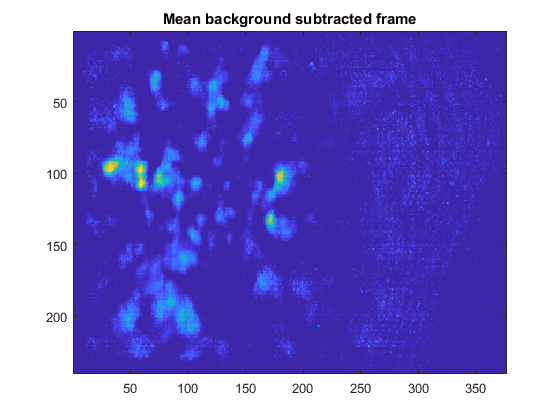

imagesc(mean(c,3))
title('Mean background subtracted frame')

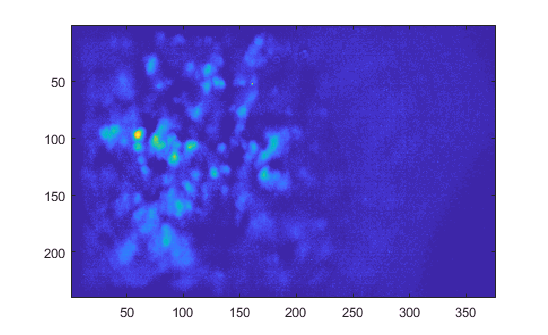

imagesc(max(c,[],3))

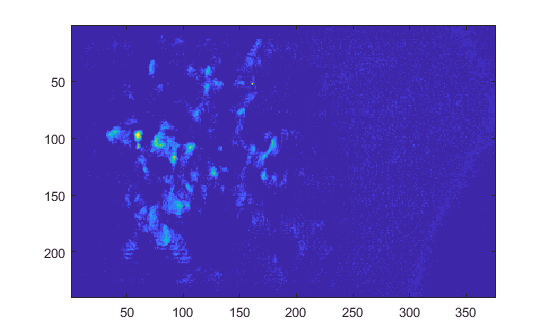

imagesc((max(c,[],3)-uint8(grad)))% uint8(mean(c,3))

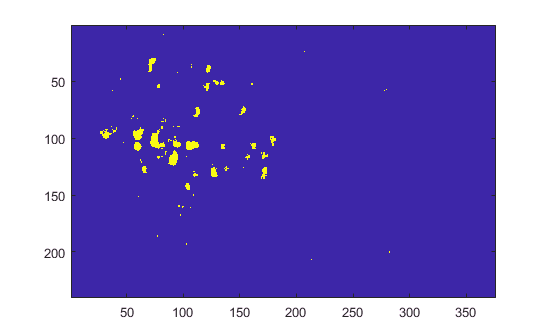


imagesc(max(c,[],3)>.13*max(max(max(c,[],3))))

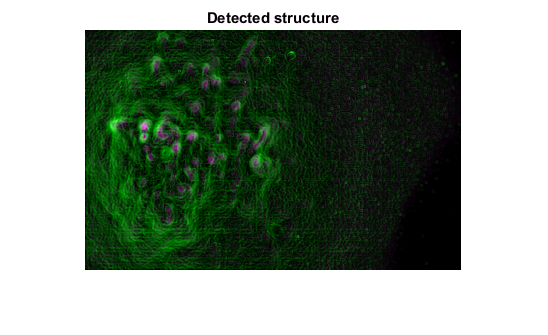


grad=imgradient(mean(comp,3));
imshowpair(grad,max(c,[],3))
title('Detected structure')

Uncomment to view volume of filtered video (shows raw traces).

%V=im2single(c);
%volumeViewer(V) 

## Select Regions of Interest

Rudimentary region of interest selection using filtered frames. bwareafilt() returns binary image with a limited amount of objects shown (second argument). Centers are then shown over the raw mean frame. 

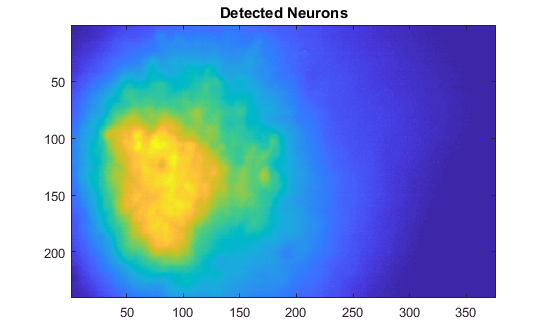

imagesc(mean(comp,3))
title('Detected Neurons')

%{
for i=1:size(c,3)
    BW2 = bwareafilt(c(:,:,i)>5*mean(mean(c(:,:,i),3)),10);
    stats = regionprops('table',BW2,'Centroid', ...
                     'MajorAxisLength','MinorAxisLength');
    % Get centers and radii of the circles
    centers(:,:,i) = stats.Centroid;
    diameters = mean([stats.MajorAxisLength stats.MinorAxisLength],2);
    radii(:,:,i) = diameters/2;
end

Subscripted assignment dimension mismatch.

%}
mimg=max(c,[],3)-medfilt2(max(c,[],3),[15 15]);
    BW2 = bwareafilt(mimg>1,50);
    stats = regionprops('table',BW2,'Centroid', ...
                     'MajorAxisLength','MinorAxisLength');
    % Get centers and radii of the circles
    centers(:,:) = stats.Centroid;
    diameters = mean([stats.MajorAxisLength stats.MinorAxisLength],2);
    radii(:,:) = diameters/2;

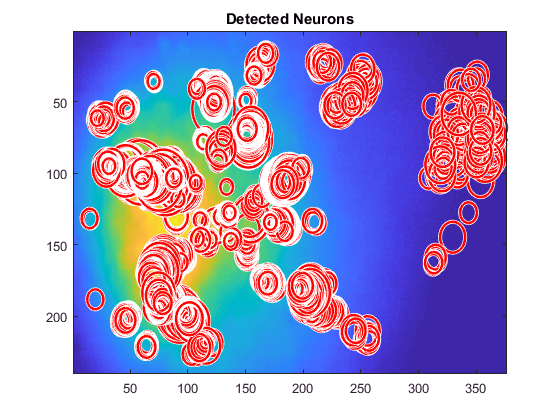

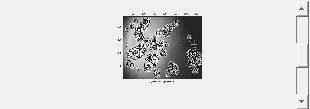

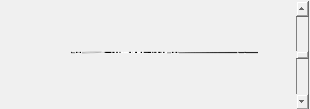

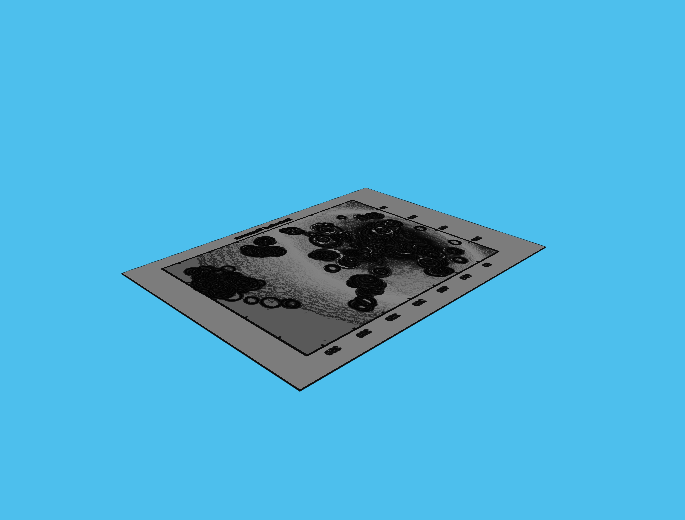

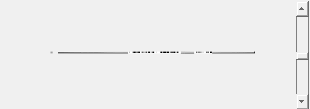

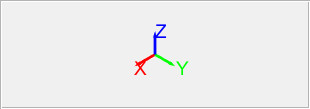

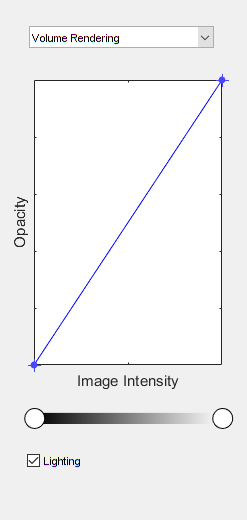

fig10=figure;
imagesc(max(c,[],3))
title('Detected Neurons')
% Plot the circles
rind=radii<7;
hold on
%for i =1:size(centers,3)
viscircles(centers(:,:),radii(:,:));
%end
hold off

Design filters for traces and cut out regions of interest from video. Below cuts out the raw traces. To cut out the filtered traces instead, change 'comp' to 'c'.

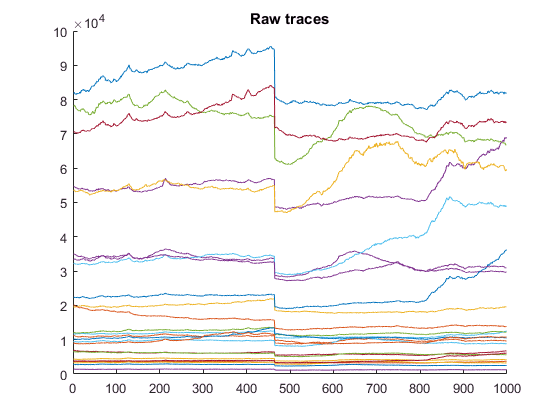

lpFilt = designfilt('lowpassiir','FilterOrder',8, ...
         'PassbandFrequency',.5,'PassbandRipple',0.2, ...
         'SampleRate',20);
hpFilt = designfilt('highpassiir','FilterOrder',8, ...
 'PassbandFrequency',2,'PassbandRipple',0.2, ...
 'SampleRate',20);
fig1=figure;
title('Raw traces')
hold on
for i = 1:size(centers,1)
    neuron{i}.cuts = comp(round(centers(i,1)-1.5*radii(i)):round(centers(i,1)+1.5*radii(i)), round(centers(i,2)-1.5*radii(i)): ...
         round(centers(i,2)+1.5*radii(i)),:);
    traces(i,:)=squeeze(sum(sum(neuron{i}.cuts,2)));
    plot(traces(i,:))
end
hold off

## Filter and Cluster Traces

Use filtering to separate calcium transients and show high frequency activity.

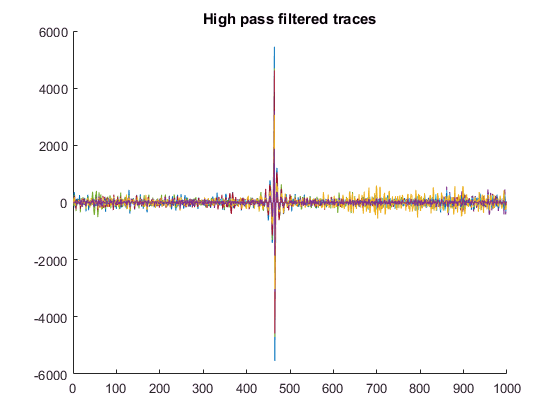

fig=figure;
hold on
for i=1:size(traces,1)
    normx=filtfilt(hpFilt,traces(i,:));
    neur(i,:)=normx;
    plot(normx)
    title('High pass filtered traces')
end
hold off

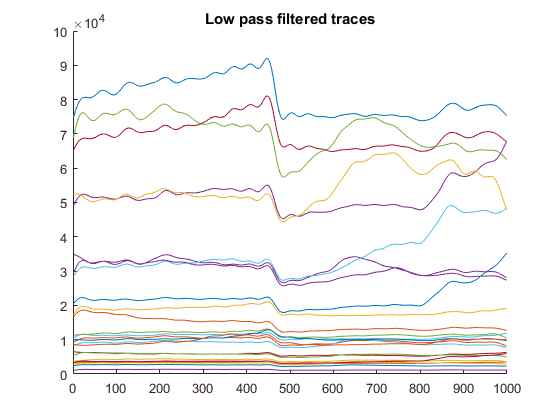

fig2=figure;
hold on
for i=1:size(traces,1)
    norml=filtfilt(lpFilt,traces(i,:));
    plot(norml)
    title('Low pass filtered traces')
end
hold off 

Cluster high frequency data using agglomerative clustering (set to 3 clusters) and plot traces.

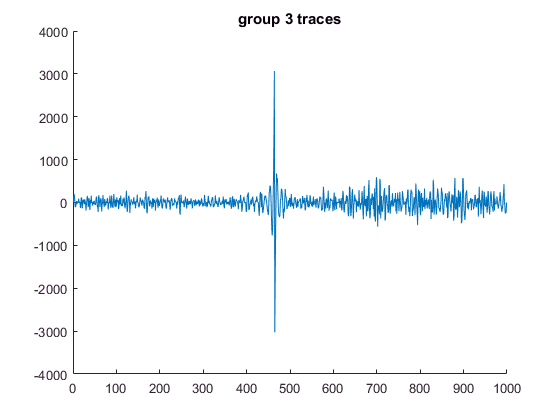

T = clusterdata(neur,3);
fig5=figure;
hold on
t3=find(T==3);
for i=1:size(find(T==3))
    plot(neur(t3(i),:))
    title('group 3 traces')
end
hold off 

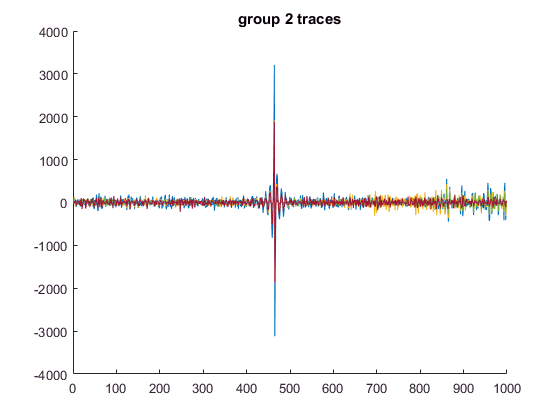

fig6=figure;
hold on
t2=find(T==2);
for i=1:size(find(T==2))
    plot(neur(t2(i),:))
    title('group 2 traces')
end
hold off 

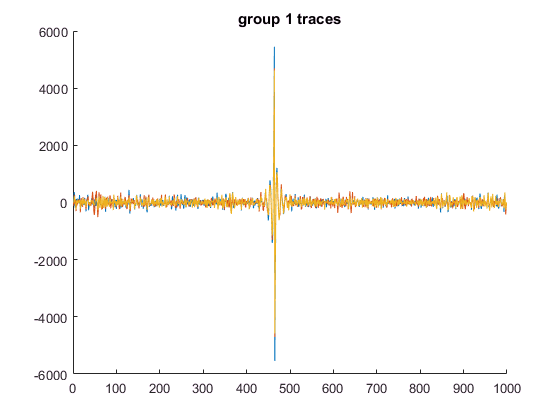

fig7=figure;
hold on
t1=find(T==1);
for i=1:size(find(T==1))
    plot(neur(t1(i),:))
    title('group 1 traces')
end
hold off 